# Note: as of 2/10/2022, this file is out of date. do not use it. it was split into two other files, "EEG_PreProcess.mlx" and "EEG_Analysis.mlx" 

# feature extraction file for EEG

% this file pulls data from .data file and extracts features based on 
% annotations 

% this analysis assumes that data has already been filtered (functions may
% be needed to be added to filter data if it is flagged as discussed with
% kavya)



## visualizing pre-analysis

% visualizing entire dataset
% h = stackedplot(allEDFs.data{'EEG'});
% ax = findobj(h.NodeChildren, 'Type','Axes');
% arrayfun(@(h)xline(h,allEDFs.annotations{'EEG'}.Onset(1,1),'LineWidth',1.5),ax)
% visualizing a portion of the dataset that was annotated as an event for a
% particular case
% stackedplot(allEDFs.data{'EEG'}(237100:249372,:)) 

    common_value = mode(allEDFs_filtered.data{'EEG'}{:,:})

common_value =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


    % find indices of most common value

## filtering out signal saturation periods

% signals that are above a certain threshold (abs(100)) will be changed to NaN.

allEDFs_filtered = allEDFs; % save allEDFs to another cell table
% determine size of table for for loop
table_size = size(allEDFs_filtered.data{'EEG'});
saturation_indx1 = find(abs(allEDFs_filtered.data{'EEG'}{:, 1}) > 100); % find saturation indices
saturation_indx2 = find(abs(allEDFs_filtered.data{'EEG'}{:, 4}) > 100); % find saturation indices

% known datapoints outside of saturation threshold
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} 
allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1}
allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4} 

% replace saturated datapoints with NaN
for i = 1:table_size(1,2)
    allEDFs_filtered.data{'EEG'}{(abs(allEDFs_filtered.data{'EEG'}{:,i}) > 50),i} = NaN;
end

% check that known datapoints are now "NaN"
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} % check that known datapoint is now "NaN"
allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1} 
allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4}

% remove common noise features
    % question - should we normalize the data and change it to the most
    % common occuring value as "zero", for example, treat 0.0013 as if it
    % is zero?
    
    % otherwise, we would just not count those values in the analysis -
    % change them to NaN
    
    
    % finding the most common value in the timetable
    common_indices = find(allEDFs_filtered.data{'EEG'}{:,:} == common_value)

common_indices =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


    
    % replacing all indices with "common_value"
%     for i = 1:table_size(1,2)
%     allEDFs_filtered.data{'EEG'}{(allEDFs_filtered.data{'EEG'}{:,i}) == common_value(1,1),i} = NaN;
%     end
    

## OR

    % normalizing to "common_value"    
%     for i = 1:table_size(1,2)
%         allEDFs_filtered.data{'EEG'}{:,i} = allEDFs_filtered.data{'EEG'}{:,i} - common_value(1,i);
%     end
       

## OR

% search for other instances of "commmon values" in other case. it may not
% always be the same value as the most often occuring value
% window in 15 second segments, check for common value, then see if the
% occurances of that common value is more than x% in a given window. if so,
% replace those values with NaN. 


## OR

% window as above statement, keep track of them in a table, first column is
% the common value in the window, second is number of occurences of that
% common value in the window. then we can replace instances of common
% values throughout the case with NaN
rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;
% 
% window_inds_filter = 1:window_size:size(allEDFs_filtered.data{'EEG'}(:,1)); % start from beginning of dataset
% % window_filter = zeros(window_size, length(channels(1,:)), length(window_inds_filter));    % preallocating for speed
% for i = 1:length(window_inds_filter)-1
%     window_filter_data(i,:) = mode(allEDFs_filtered.data{'EEG'}{window_inds_filter(1,i):window_inds_filter(1,i)+window_size-1,:});
%     window_filter_occurances(i,:) = find(allEDFs_filtered.data{'EEG'}{window_inds_filter(1,i):window_inds_filter(1,i)+window_size-1,:} == window_filter_data(1,i));
%     % TODO = remove section where number is repeated excessively
% end

%scan thru data, find starting and ending points that are above a certain
%threshold, set to NaN. run a loop to check next values. start tallying
%values that are similar, when they change to a certain threshold, replace
%those values with NaN and restart the tally



%y = stackedplot(allEDFs_filtered.data{'EEG'}) % visualizing post-filtering
%y.AxesProperties(1).YLimits = [-200 200];

% method that kavya came up with during out meeting 1/8/2022 to replace
% saturation indices with nan.
%saturation_indx = find(allEDFs_filtered.data{'EEG'}{:, 1} > 100);
%for i = 1:length(saturation_indx)
%    allEDFs_filtered.data{'EEG'}{saturation_indx(i), 1} = nan;
%end


## baseline mean determination

% find index of first instance of "intubat" (intubation)
index1 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'intubat', 'IgnoreCase',true));
onset1 = allEDFs_filtered.annotations{'EEG'}.Onset(index1(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset1);
intubation_Index = find(index)

intubation_Index = 259585


% find index of first instance of "incis" (incision)
index2 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'incis', 'IgnoreCase',true));
onset2 = allEDFs_filtered.annotations{'EEG'}.Onset(index2(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset2);
incision_Index = find(index)

incision_Index = 678529

% run function to determine start index for each EEG channel
channels = {'EEGFp1_Cp3','EEGFpz_Cp3', 'EEGCp3_T3', 'EEGT3_O1', 'EEGFp2_Cp4', 'EEGFpz_Cp4', 'EEGCp4_T4', 'EEGT4_O2'}

channels = 1×8 cell array
    {'EEGFp1_Cp3'}    {'EEGFpz_Cp3'}    {'EEGCp3_T3'}    {'EEGT3_O1'}    {'EEGFp2_Cp4'}    {'EEGFpz_Cp4'}    {'EEGCp4_T4'}    {'EEGT4_O2'}


start_index = nan(1,table_size(1,2));
for k = 1:length(channels)
    start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
end
start_index % check for baseline start

start_index =         4737        4737        4737        4737        4738        4737        4737        4737



% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
diffs = diff(start_index);
diffs = max(abs(diffs(diffs >= 0)));
if (diffs > 5)
    error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
end



% determining the baseline for all channels
baseline_preIntubation = nan(1,8);
baseline_postIntubation = nan(1,8);
baseline_Total = nan(1,8);
for i = 1:table_size(1,2)
    baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
    baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
    baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
end
baseline_preIntubation

baseline_preIntubation =    -0.0386   -0.1125    0.0016    0.0806    0.0278   -0.0902   -0.1275    0.0876


baseline_postIntubation

baseline_postIntubation =    -0.0167    0.0423   -0.1430    0.0109   -0.0028    0.2266   -0.1783   -0.0128


baseline_Total

baseline_Total =    -0.0223    0.0025   -0.1055    0.0291    0.0051    0.1446   -0.1653    0.0130



% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel


% window_inds = start_index(1,1):window:intubation_Index
% window_inds = max(start_index):window_size:intubation_Index;
% baseline_window = zeros(window_size, length(channels(1,:)), length(window_inds)); % pre allocate for speed
% for i = 1:length(window_inds)
%     baseline_window(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds(i):window_inds(i)+window_size-1, :};
%     % TODO = remove section where number is repeated excessively
% end
% mean_baseline = mean(baseline_window, 3, 'omitnan')
% 
% 
% preintubation_baseline_window = baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)
% postintubation_baseline_window = baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)
% total_baseline_window = baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)

% mean(allEDFs_filtered.data{'EEG'}{start_index(1,1):intubation_Index,1},'omitnan')
% allEDFs_filtered.data{'EEG'}{intubation_Index + 1,2}



    window_inds = max(start_index):window_size:intubation_Index; % finding window indices 15 seconds apart
    
    % create and populate 3D array from baseline range
    baseline_windows = zeros(window_size, length(channels(1,:)), length(window_inds));
    for i = 1:length(window_inds)
        baseline_windows(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds(i):window_inds(i)+window_size-1, :};
    end
    
    % average values to return one baseline window
   % mean_baseline = mean(baseline_windows, 3, 'omitnan');

## analysis 

% from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline



% window entire study after baseline
window_inds_analysis = intubation_Index+1:window_size:size(allEDFs_filtered.data{'EEG'}(:,1));
window_analysis = zeros(window_size, length(channels(1,:)), length(window_inds_analysis));    % preallocating for speed
for i = 1:length(window_inds_analysis)-1
    window_analysis(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds_analysis(i):window_inds_analysis(i)+window_size-1, :};
    % TODO = remove section where number is repeated excessively
end

% do either/both percentage change model or GMM in this area
    % can we feed the GMM the raw data or do we have to extract the
    % features from the raw data ourselves and feed it to the GMM






% add function that determines the GMM parameters from the baseline windows



gm = fitgmdist(preintubation_baseline_window, 1) % how do we know how many components a GMM should be?

Unrecognized function or variable 'preintubation_baseline_window'.

properties(gm); % list all properties for the GMM. Can be accessed using format "gm.NumVariables" (dot notation)
% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model
x = allEDFs_filtered.data{'EEG'};
%  y=fft(x{:,1}); % giving all NaN values atm
%  PS=abs(y).^2; 
%  N=table_size(1,1); 
%  fs=1000; 
%  freq=(1:N/2)*fs/N; 
%  plot(freq,PS)

% % compute fast fourier transform for baseline window
%transforms_baseline = fft(baseline_windows, 133, 3) % remove hard-coded second argument

% compute fast fourier transform of each window in the analysis portion




Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

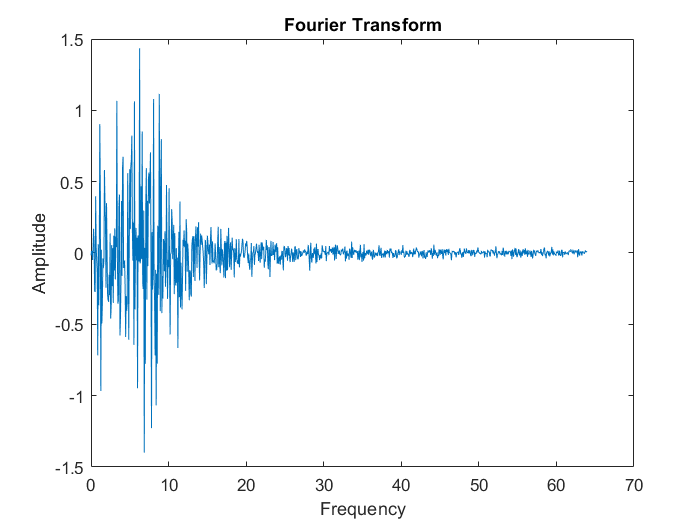

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

%delta = int(single_sided_transform(:,1,1),1,3)
%pspectrum(transforms_analysis(:,1,1), Fs)


% try to run bandpower function
% try 
%     for i = 1:size(window_analysis)(1,3)
%         delta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         theta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         alpha = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         beta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         gamma = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%     end
% catch ME
%     
% end
% z = fillmissing(window_analysis, 'movmedian', 10)
% delta = bandpower(window_analysis(:,:,4), Fs, [1 3])


wind_analysis_size = size(window_analysis)

Unrecognized function or variable 'window_analysis'.

caught_nans = {};
frequency_band = [1 3];
for i = 1:wind_analysis_size(1,3)
    data = window_analysis(:,:,i);
    try
        delta(i,:) = bandpower(data, Fs, frequency_band);
    catch
        [rows, columns] = find(isnan(data));
        caught_nans{i,1} = [rows columns];
        [B, BG, BP] = groupcounts(caught_nans{i,1}(:,2));
        
        if (length(caught_nans{i,1}) > 200) % if total occurances of NaN values exceeds thresholds, go to next loop iteration
            continue;
        end
        
        if (isempty(BG(B>=50))) % if column of values has more than threshold number of NaN in a row, go to next loop iteration
          continue;
        end
          
          temp = fillmissing(data, 'movmedian', 100);
          delta(i,:) = bandpower(temp, Fs, frequency_band);
    end
end

% catch exception for NaN values

%delta = bandpower(window_analysis(1:582 584:end,1,1), Fs, [1 3])

plot(window_analysis(575:585, :, 4))
xlim([6 9])
ylim([-50 30])
legend(channels)
plot(window_analysis(:, 6, 4))

% unknowns: estimating k; putting new data into a model to get probability
% that it fits the model -> (posterior function)

% start with one channel/one feature to get a sense of if its working
% properly    


% s = spectrogram(allEDFs_filtered.data{'EEG'})
s = stft(allEDFs_filtered.data{'EEG'})


stft(allEDFs_filtered.data{'EEG'}{:,1})


%NOTE: GMM requires Statistics and Machine Learning Toolbox
%GMModel = fitgmdist(preintubation_baseline_window,length(channels(1,:))) 







% Note: for determining large amplitude changes between hemispheres,
% a table will be created containing the percentage change between the
% signal at a particular timepoint as compared to the baseline for each
% channel. if signals deviate for a minute or more, it will be marked as an
% event. 

% percent change
for i = 1:table_size(1,2)
    percent_change_table(:,i) = allEDFs_filtered.data{'EEG'}{incision_Index+1:end, channels(1,i)};
end
    % values will be saved to a new data table and analyzed from there
    percent_change_table = allEDFs_filtered.data{'EEG'}{stop_index+1:end,'EEGFp1_Cp3'};
    % change = 100*((signal-baseline)/baseline)
    percent_table_size = size(percent_change_table);
    percent_table_size = percent_table_size(1,1);
    for i = 1:percent_table_size
        percent_change_table(i) = 100 * abs((percent_change_table(i)-baseline)/baseline);
    end

% scan for features based on EEG alerts
    % plot percent change table with markers at 10 and 20 percent changes
    % from baseline 
    plot(percent_change_table(:,1))
    yline(10, '-','10 percent')
    yline(20,'-','20 percent')
    % text search for electrocautery and plot that over actual data
    
    

% isolation of features here

% Gaussian Mixture Model
[x,y,z] = baseline_mean(allEDFs)



## NOTES

% at some point I would like to create unit tests to verify that this code
% is able to handle a wide variety of datasets/data conditions and still
% perform well. I would like to generally how I would like the code to be
% written before doing this.

% baseline is supposed to be determined before CPB. I do not
% currently see in the annotations when that occurs, so I have
% selected a window based on what the OR team says that they
% currently do (see baseline.mlx for more details)

% not all of the annotations for all of the cases contain the word
% "incision", so it may be necessary to use a pre-incision baseline
% determination method, unfortunately. Since the OR team determines
% baselines both before and after incision, I would like to determine our
% baseline determination to emulate theirs, at least in the beginning
% stages of analysis

